% MAIN script: builds a random DC microgrid, draws it, and simulates it.
clear; clc; close all;
rng(7);

%% ----------- Random microgrid generation -----------
N = 6;                                     % number of DGs
areaSide = 8;
pos = areaSide*(rand(N,2)-0.5);            % random 2D positions

% Reasonable DG parameter ranges
Lvals = 1e-3 * (0.9 + 0.2*rand(N,1));      % 0.9–1.1 mH
Cvals = 1e-3 * (0.9 + 0.2*rand(N,1));      % 0.9–1.1 mF
Rfvals= 0.05 + 0.1*rand(N,1);              % 0.05–0.15 Ohm
vref  = 48*ones(N,1);                      % 48 V nominal

% --- DGs with per-node ratings ---
%% ---------------- DGs with fixed Vr=48 and intentional ZI-load imbalance ----------------
Vr_fixed = 48;                     % rated bus voltage for all DGs
pctHeavy = 0.6;                   % fraction of "heavy" nodes (forces network flows)
idxHeavy = randperm(N, ceil(pctHeavy*N));

% Power rating bands (W) for light/heavy converters (affects Irated)
Pr_light = [100 200];              % 2.5–5 A @ 48V
Pr_heavy = [500 600];              % 5.4–8.8 A @ 48V

% Impedance safety bounds (Ohm)
DGs = repmat(DG(1,struct()), 1, N);
for k = 1:N
    Vr_k = Vr_fixed;                % keep 48 V for every DG

    % Converter rating (Irated) via light/heavy bands
    if ismember(k, idxHeavy)
        Pr_k = randi(Pr_heavy);     % heavier converter capability
    else
        Pr_k = randi(Pr_light);
    end
    Ir_k = 2*Pr_k / Vr_k;             % A (converter rated current)

    % --- Z/I split for the **load** at this node (not converter rating) ---
    % Start with a Z share alphaZ ~ N(0.6,0.2), clamp, then compute P_Z, P_I.
    alphaZ = 0.6 + 0.2*randn();
    % Add per-node jitter to **load** power magnitude around converter rating to create mismatch
    Pload_k = Pr_k * (1.10 + 0.30*(2*rand()-1));   % ~Pr_k ±15%, biased +10% to induce imports
    PZ_k = alphaZ * Pload_k;              % Z-part power (W)
    PI_k = Pload_k - PZ_k;                 % I-part power (W)

    % Convert Z power to impedance and I power to constant current
    RL_k   = Vr_k^2 / PZ_k;   % Ohm
    Ibar_k = (PI_k / Vr_k) * (0.8 + 0.4*rand());  % A

    % --- Build DG object ---
    params = struct( ...
        'L',Lvals(k), 'C',Cvals(k), 'Rf',Rfvals(k), ...
        'RL', RL_k, 'Ibar', Ibar_k, ...           % ZI load parameters (→ plant)
        'Vrated', Vr_k, 'Irated', Ir_k, ...       % converter ratings
        'u_s', Vr_k, ...                         % start input near rated voltage
        'pos', pos(k,:), ...
        'x', [1.5*randn(1)*Vr_k; 1.5*randn(1)*Ir_k], ...                       % initial state [vC;iL]
        'iload_fun', @(t) 0, ...                % no time ripple now (add later if needed)
        'K', [0 0] );
    DGs(k) = DG(k, params);
end



%% ----------- Proximity-based graph with min-length & length-proportional R -----------
lines = {};
idc   = 1;

% --- Tunables ---
minLen      = 1.0;                 % [arb units] minimum allowable line length
proxRadius  = 3.0;                 % initial proximity radius (will grow if not connected)
rho_per_len = 0.30;                % [Ohm / length-unit] base resistance per unit length
randSpan    = 0.20;                % ±20% multiplicative randomness on R

% Pairwise distances
D = squareform(pdist(pos));        % NxN Euclidean distances

% Helper to (re)build edge list for a given radius
buildEdges = @(R) find(triu((D >= minLen) & (D <= R), 1));   % upper-triangular linear indices

% Grow radius until connected (or until it’s obviously enough)
maxTries = 10;
for attempt = 1:maxTries
    Eidx  = buildEdges(proxRadius);
    [ii, jj] = ind2sub([N N], Eidx);
    Gtmp = graph(ii, jj, D(Eidx), N);
    if numedges(Gtmp) == 0
        proxRadius = proxRadius * 1.5;    % nothing yet; expand search
        continue;
    end
    comps = conncomp(Gtmp);
    if numel(unique(comps)) == 1
        break;                             % connected!
    else
        proxRadius = proxRadius * 1.35;    % not connected; expand and retry
    end
end

% If still not connected, force connectivity with an MST over *eligible* pairs
if numel(unique(comps)) ~= 1
    % Allow all pairs >= minLen for MST
    W = D;
    W(D < minLen) = inf;                   % disallow too-short edges
    Gfull = graph(W);
    T = minspantree(Gfull,'Method','dense');
    ii = [ii; T.Edges.EndNodes(:,1)];
    jj = [jj; T.Edges.EndNodes(:,2)];
end

% Create TransmissionLine objects; R ∝ length with randomness
for e = 1:numel(ii)
    i = ii(e); j = jj(e);
    len_ij = D(i,j);
    if isinf(len_ij) || len_ij < minLen, continue; end
    mult = 1 + randSpan*(2*rand()-1);      % in [1-randSpan, 1+randSpan]
    R_ij = rho_per_len * len_ij * mult;
    lines{end+1} = TransmissionLine(idc, i, j, R_ij); %#ok<AGROW>
    idc = idc + 1;
end

Lines = [lines{:}];

% Assemble microgrid
net = DCMicrogrid(DGs, Lines);

% ------ Steady state with epsilon matrices (equal current sharing) ------
ss = net.solveSteadyState();

fprintf('Steady-state solve: %s\n', ss.info);

Steady-state solve: Successfully solved 


ss.epsI

ans = 0.5215

ss.epsV

ans =     0.9627
    0.9612
    0.9573
    0.9711
    0.9812
    0.9934


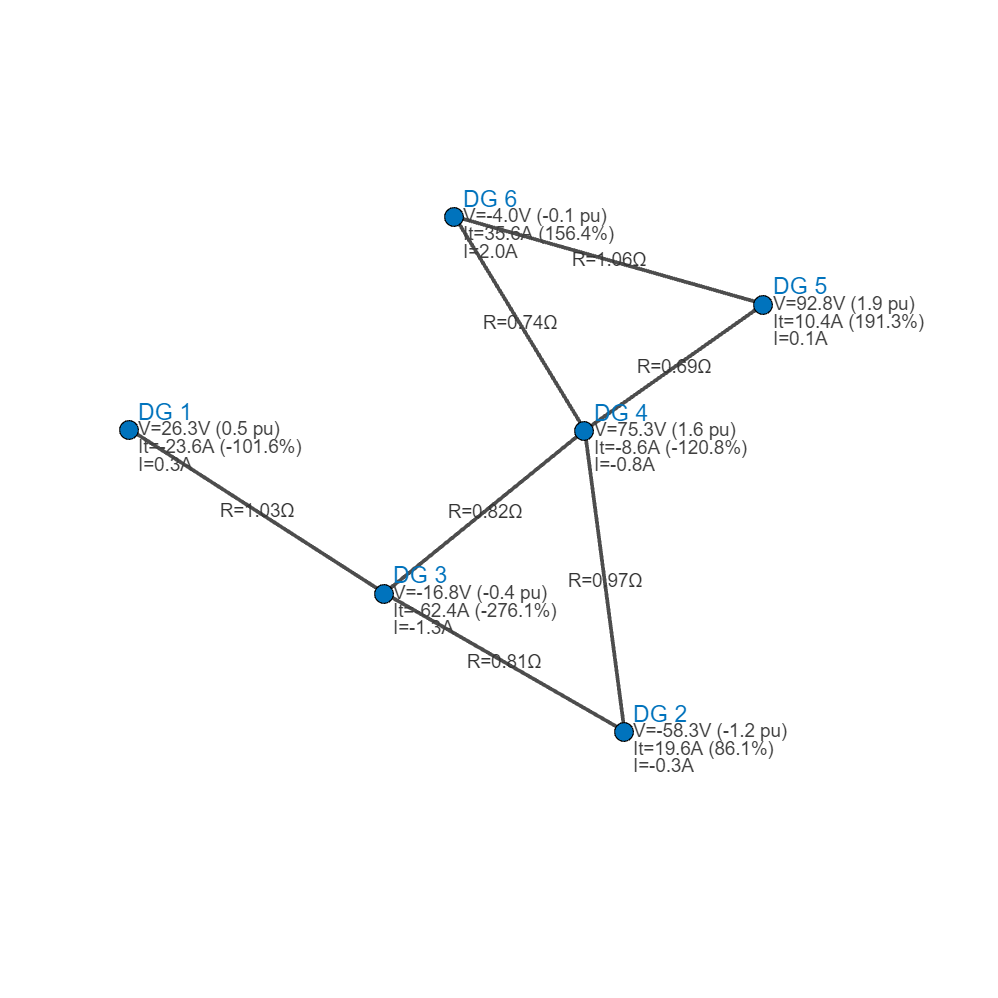

Saved figure as: Results/DCMG.png and Results/DCMG.fig



% %% ---------------- Draw topology ----------------
fig0 = figure('Color','w','Name','Topology');

% Redraw topology: electrical (solid) + inferred comm (dashed)
figure(fig0); clf; ax0 = axes(fig0); net.draw(ax0);
% title(ax0,'DC Microgrid: Electrical (solid) and inferred communication (dashed)');
adjustAxesPadding4(ax0, 0, 0, 0, 0);
saveFigureHighRes('DCMG', ...
    'Width', 6, 'Height', 6, 'Units', 'inches', ...
    'DPI', 600, 'FontSize', 6);


% 1) Start at the steady state and enable integral action
dissDesign = 0;

% %% --------- Design K freely (dense), then infer comm topology ----------
if dissDesign 

    % ---- LOCAL dissipativity stage (per DG) ----
    net.designLocalK();
    
    % ---- GLOBAL distributed stage (uses Pblk and line physics) ----
    % Option A: dense K
    net.designGlobalDistributedK();
    
    % Option B: enforce K sparsity from electrical neighbors:
    % mask = (net.Y > 0);                   % NxN boolean (off-diagonals)
    % glob = net.designGlobalDistributedK_fromLocal(Pblk, struct('alpha',0.22,'use_KL',true,'sparsityMask',mask,'penalty',1e-3));
    
    % fprintf('Local stage done. Global stage: %s\n', net.K);

else
    % net.designLocalK()
    % net.designGlobalDistributedK();

    outK = net.designKFree();
    % fprintf('Free-K design: %s\n', outK.info);

end

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                    Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|       Matrix inequality 12x12|              1 to 1|
|   #2|   Element-wise inequality 1x1|          0.001 to 1|
|   #3|       Matrix inequality 12x12|       1 to 2209.994|
|   #4|      Equality constraint 6x12|    0.94431 to 5.057|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++

MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 223             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 73              
  Matrix vari

K =     0.9736    0.0000    0.0000   -0.0000   -0.9736    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.1013   -0.9783   -0.0000    0.0722   -0.0000    0.0625    0.0000    0.0319   -0.0000    0.0479   -0.0000    0.0198
    0.0000    0.0000    2.2674    0.0000   -1.2374   -0.0000   -1.0300    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0676   -0.0091   -0.9837   -0.0000    0.0339    0.0000    0.0216   -0.0000    0.0756   -0.0000    0.0315
   -0.9736    0.0000   -1.2374    0.0000    3.4315   -0.0000   -1.2205   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0613   -0.0000   -0.0355    0.0612   -0.9956    0.0000    0.0206   -0.0000    0.0732   -0.0000    0.0315
   -0.0000   -0.0000   -1.0300    0.0000   -1.2205   -0.0000    5.0570   -0.0000   -1.4543   -0.0000   -1.3522   -0.0000
    0.0000   -0.0354   -0.0000   -0.0256   -0.0000   -0.0233    0.0074   -1.1154   -0.0000    0.0750   -0.0000    0.0498
    0.0000   -0.0000    0.00

obj =   DCMicrogrid with properties:

        DGs: [1×6 DG]
      Lines: [1×7 TransmissionLine]
          N: 6
          M: 7
          G: []
          A: [12×12 double]
       BBar: [12×12 double]
          E: [12×6 double]
          B: [12×6 double]
          D: [12×6 double]
       DBar: [12×6 double]
        u_s: [6×1 double]
       wBar: [6×1 double]
          Y: [6×6 double]
       YBar: [6×6 double]
        x_s: [12×1 double]
        K_L: [6×12 double]
          K: [6×12 double]
    commAdj: []
          z: [6×1 double]
        K_I: []


ans = 1.0e+03 *

  -5.9356 + 0.0000i
  -4.2129 + 0.0000i
  -0.6494 + 0.8368i
  -0.6494 - 0.8368i
  -0.9735 + 0.9596i
  -0.9735 - 0.9596i
  -1.5084 + 0.9761i
  -1.5084 - 0.9761i
  -2.8747 + 0.0000i
  -1.3323 + 0.0000i






% Infer communication adjacency from K and store it
net.buildCommAdjFromK(1e-4);   % threshold for nonzero blocks
net.K

ans =     0.1013   -0.9783   -0.0000    0.0722   -0.0000    0.0625    0.0000    0.0319   -0.0000    0.0479   -0.0000    0.0198
    0.0000   -0.0676   -0.0091   -0.9837   -0.0000    0.0339    0.0000    0.0216   -0.0000    0.0756   -0.0000    0.0315
    0.0000   -0.0613   -0.0000   -0.0355    0.0612   -0.9956    0.0000    0.0206   -0.0000    0.0732   -0.0000    0.0315
    0.0000   -0.0354   -0.0000   -0.0256   -0.0000   -0.0233    0.0074   -1.1154   -0.0000    0.0750   -0.0000    0.0498
    0.0000   -0.0463   -0.0000   -0.0780   -0.0000   -0.0720    0.0000   -0.0654    0.0036   -0.9639    0.0000    0.0258
    0.0000   -0.0201   -0.0000   -0.0341   -0.0000   -0.0326    0.0000   -0.0455   -0.0000   -0.0271    0.0191   -1.0388


net.commAdj

ans =      1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1


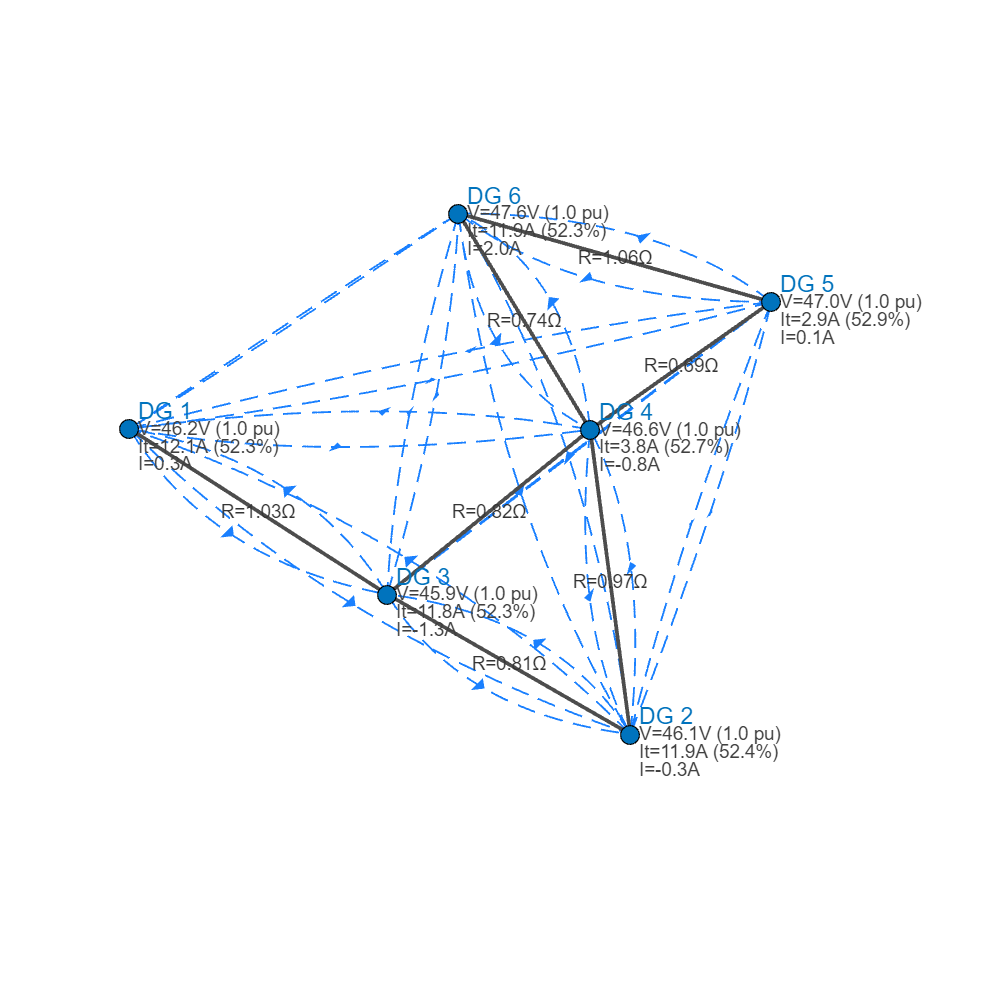

Saved figure as: Results/Stabilizing_DCMG_Topology.png and Results/Stabilizing_DCMG_Topology.fig





% 
%% ----------------- Simulation ------------------
tspan = [0 0.05];          % seconds
x0 = net.getStateVector();

[t, X] = net.simulate(tspan, x0);

% Unstack voltages and currents
iL = zeros(numel(t), N);
vC = zeros(numel(t), N);
for k = 1:N
    vC(:,k) = X(:, 2*k-1);
    iL(:,k) = X(:, 2*k);
end
    
% %% ---------------- Draw topology ----------------
fig1 = figure('Color','w','Name','Topology');

% Redraw topology: electrical (solid) + inferred comm (dashed)
figure(fig1); clf; ax1 = axes(fig1); net.draw(ax1);
% title(ax1,'DC Microgrid: electrical (solid) and inferred communication (dashed)');
adjustAxesPadding4(ax1, 0, 0, 0, 0);
if dissDesign
    saveFigureHighRes('DCMG_Topology', ...
    'Width', 6, 'Height', 6, 'Units', 'inches', ...
    'DPI', 600, 'FontSize', 6);
else
    saveFigureHighRes('Stabilizing_DCMG_Topology', ...
    'Width', 6, 'Height', 6, 'Units', 'inches', ...
    'DPI', 600, 'FontSize', 6);
end    



% % Verify physics at solution (should be ~zero)
Am = net.A; Em = net.E; Bm = net.B; YB = net.YBar;
xss = ss.x_ss; uss = ss.u_s; V = ss.V_ss; Iline = YB*V;
res = Am*xss + Em*Iline + Bm*uss + Em*net.wBar;
fprintf('||steady-state residual||_2 = %.3e\n', norm(res));

||steady-state residual||_2 = 2.376e-11





% %% ----------------- Per-unit plots (w.r.t. steady state) -----------------
% ss.V_ss : N×1 steady-state bus voltages
% ss.I_tss: N×1 steady-state inductor (converter) currents

V_ss = ss.V_ss'                     % 1×N

V_ss =    46.2115   46.1387   45.9506   46.6151   47.0979   47.6848


I_tss = ss.I_tss'                    % 1×N

I_tss =    12.1025   11.8635   11.7766    3.7155    2.8464   11.8853



vC_pu = vC ./ V_ss                     % T×N (implicit expansion in new MATLAB)

vC_pu =     0.5698   -1.2630   -0.3666    1.6144    1.9702   -0.0837
    0.5695   -1.2618   -0.3664    1.6129    1.9696   -0.0826
    0.5692   -1.2607   -0.3662    1.6115    1.9691   -0.0816
    0.5688   -1.2596   -0.3661    1.6100    1.9686   -0.0805
    0.5685   -1.2585   -0.3659    1.6085    1.9680   -0.0795
    0.5669   -1.2529   -0.3650    1.6012    1.9653   -0.0742
    0.5653   -1.2474   -0.3642    1.5939    1.9626   -0.0690
    0.5637   -1.2419   -0.3633    1.5866    1.9599   -0.0638
    0.5621   -1.2364   -0.3625    1.5794    1.9572   -0.0587
    0.5542   -1.2092   -0.3583    1.5441    1.9437   -0.0332


iL_pu = iL ./ I_tss                % T×N

iL_pu =    -1.9474    1.6509   -5.2950   -2.3162    3.6685    2.9995
   -1.9464    1.6528   -5.2922   -2.3167    3.6648    2.9999
   -1.9454    1.6548   -5.2894   -2.3172    3.6611    3.0004
   -1.9444    1.6568   -5.2867   -2.3176    3.6574    3.0009
   -1.9434    1.6587   -5.2839   -2.3181    3.6536    3.0014
   -1.9384    1.6685   -5.2702   -2.3203    3.6351    3.0039
   -1.9334    1.6783   -5.2564   -2.3224    3.6167    3.0063
   -1.9284    1.6880   -5.2427   -2.3244    3.5983    3.0087
   -1.9235    1.6977   -5.2290   -2.3263    3.5800    3.0111
   -1.8985    1.7455   -5.1608   -2.3347    3.4894    3.0225


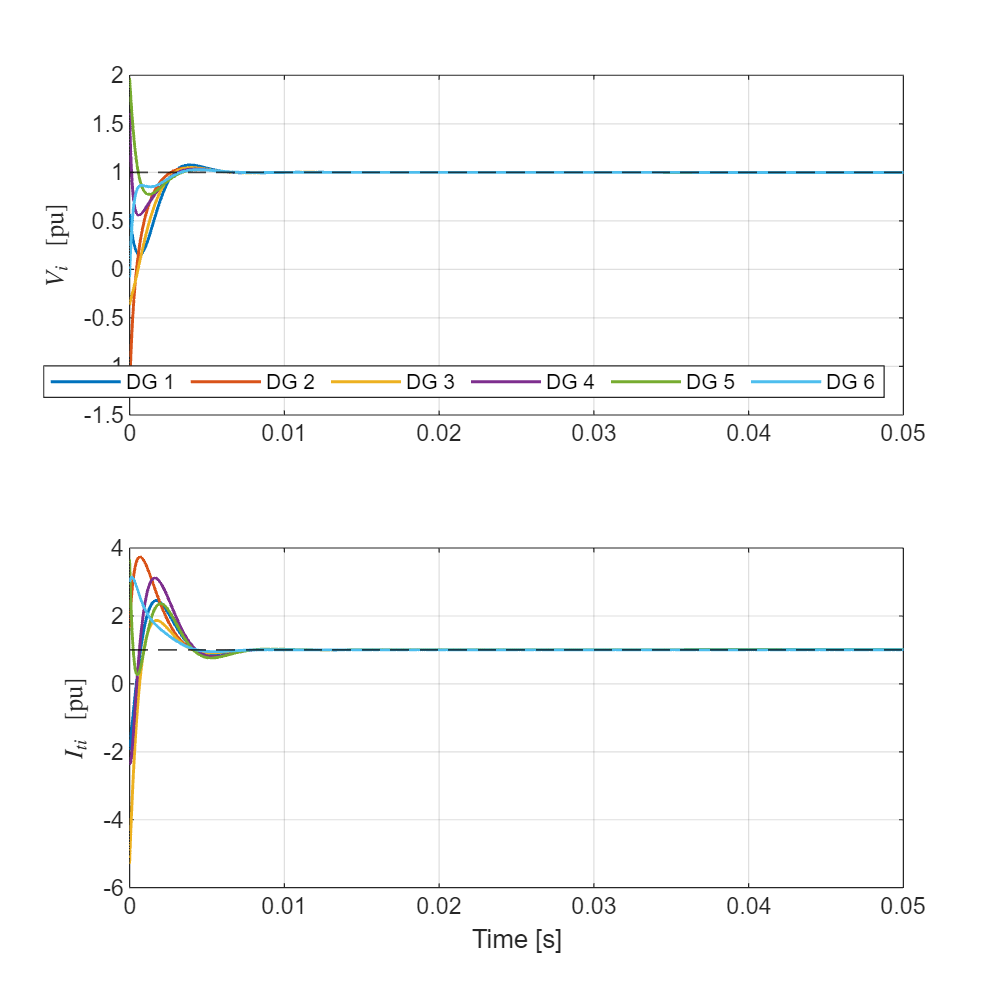

Saved figure as: Results/Stabilizing-Design.png and Results/Stabilizing-Design.fig



fig2 = figure('Color','w','Name','Per-Unit States over time');

subplot(2,1,1)
plot(t, vC_pu, 'LineWidth', 1.25);
yline(1,'k--','LineWidth',0.8); grid on;
ylabel('$V_i\ $ [pu]',Interpreter='latex'); 
% title('Bus voltages (per unit)');
legend(arrayfun(@(k) sprintf('DG %d',k), 1:N, 'UniformOutput',false), Location="south", Orientation="horizontal");

subplot(2,1,2)
plot(t, iL_pu, 'LineWidth', 1.25);
yline(1,'k--','LineWidth',0.8); grid on;
ylabel('$I_{ti}\ $ [pu]',Interpreter='latex'); xlabel('Time [s]'); 
% title('Inductor currents (per unit)');

if dissDesign
saveFigureHighRes('Model-Based-Design', ...
    'Width', 6, 'Height', 6, 'Units', 'inches', ...
    'DPI', 600, 'FontSize', 8);
else
    saveFigureHighRes('Stabilizing-Design', ...
    'Width', 6, 'Height', 6, 'Units', 'inches', ...
    'DPI', 600, 'FontSize', 8);
end



%% -------- Example: compute line currents at final state --------
vC_end = vC(end,:).';
fprintf('\nLine currents at t=%.3f s:\n', t(end));


Line currents at t=0.050 s:


for e = 1:numel(Lines)
    i = Lines(e).i; j = Lines(e).j;
    i_ij = Lines(e).current(vC_end(i), vC_end(j));
    fprintf('  Line %2d: %d-%d  I_ij = %+6.3f A  (R=%.2f Ω)\n', ...
        Lines(e).id, i, j, i_ij, Lines(e).R);
end

  Line  1: 1-3  I_ij = +0.257 A  (R=1.03 Ω)
  Line  2: 2-3  I_ij = +0.235 A  (R=0.81 Ω)
  Line  3: 2-4  I_ij = -0.485 A  (R=0.97 Ω)
  Line  4: 3-4  I_ij = -0.807 A  (R=0.82 Ω)
  Line  5: 4-5  I_ij = -0.698 A  (R=0.69 Ω)
  Line  6: 4-6  I_ij = -1.445 A  (R=0.74 Ω)
  Line  7: 5-6  I_ij = -0.556 A  (R=1.06 Ω)


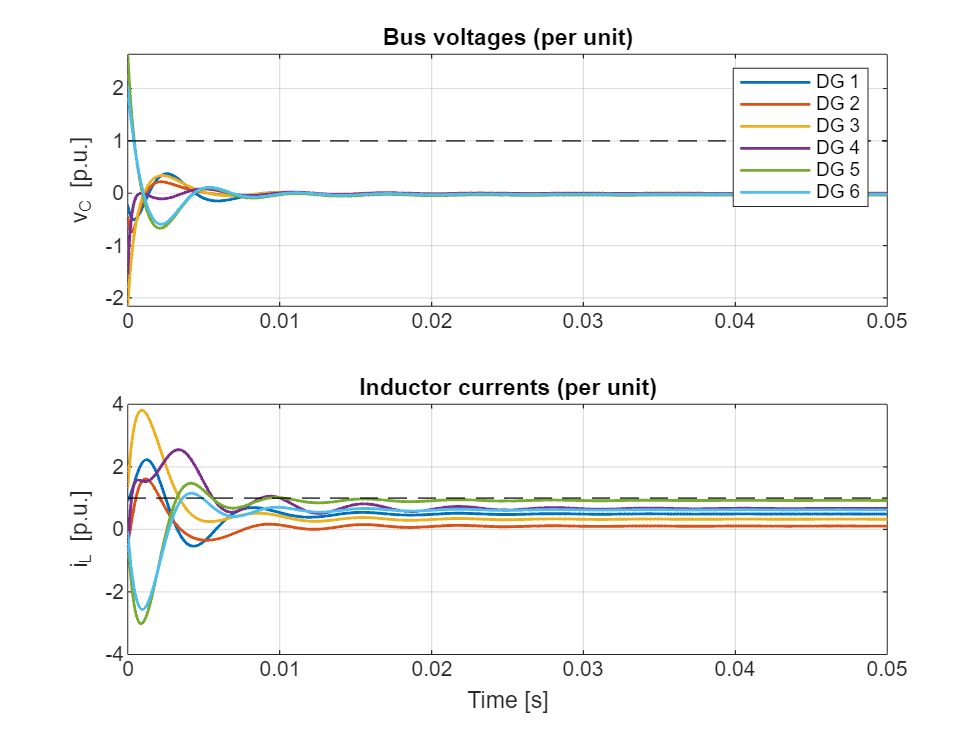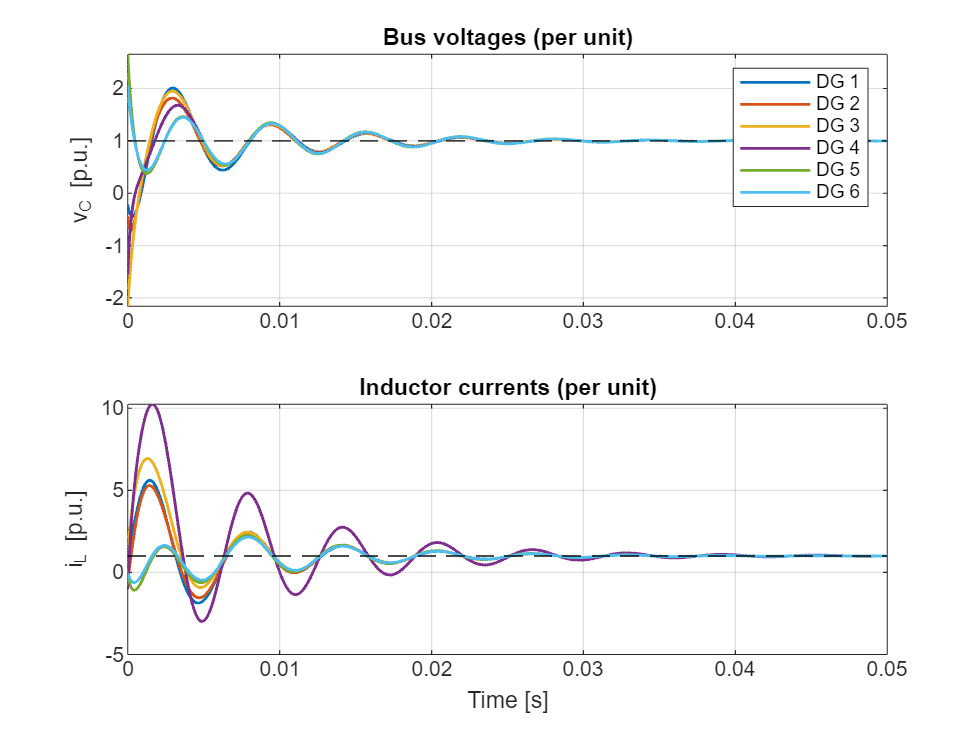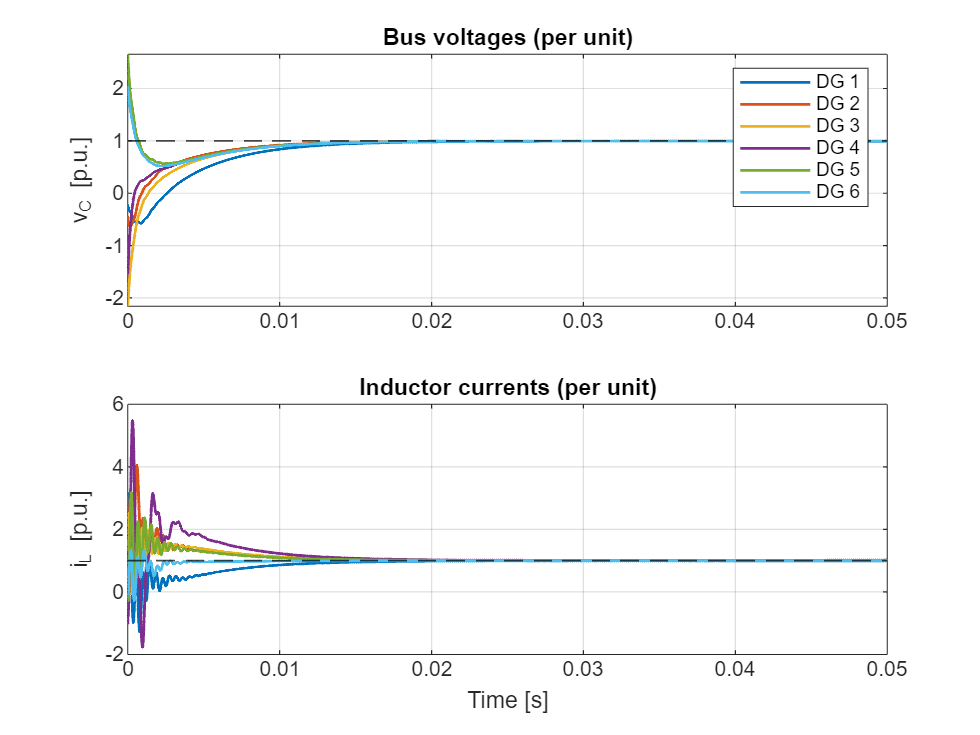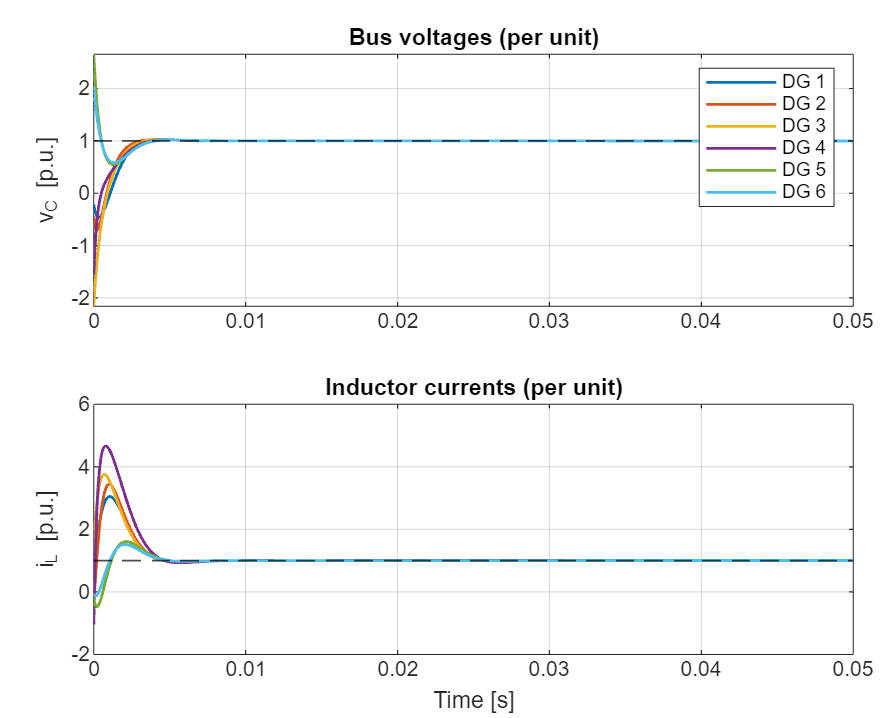

function saveFigureHighRes(baseName, varargin)
%SAVEFIGUREHIGHRES Save a figure as high-res PNG and FIG, with padding.
%
%   saveFigureHighRes('myPlot')
%   saveFigureHighRes('myPlot','Width',6,'Height',4,'FontSize',14,'DPI',300)
%   saveFigureHighRes('myPlot','Padding',20)   % padding in points

    % ---- Defaults ----
    defaults.Figure   = gcf;
    defaults.Width    = 6;           % in Units
    defaults.Height   = 4;           % in Units
    defaults.Units    = 'inches';    % 'inches','centimeters',...
    defaults.DPI      = 300;
    defaults.FontSize = 14;
    defaults.Padding  = 20;          % points around content

    % ---- Parse inputs ----
    p = inputParser;
    addRequired(p,'baseName',@(x)ischar(x) || isstring(x));
    addParameter(p,'Figure',   defaults.Figure);
    addParameter(p,'Width',    defaults.Width,  @isnumeric);
    addParameter(p,'Height',   defaults.Height, @isnumeric);
    addParameter(p,'Units',    defaults.Units,  @ischar);
    addParameter(p,'DPI',      defaults.DPI,    @isnumeric);
    addParameter(p,'FontSize', defaults.FontSize,@isnumeric);
    addParameter(p,'Padding',  defaults.Padding,@isnumeric);

    parse(p,baseName,varargin{:});
    R = p.Results;

    fig = R.Figure;

    % ---- Set figure size on screen ----
    set(fig,'Units',R.Units);
    pos = get(fig,'Position');
    pos(3) = R.Width;
    pos(4) = R.Height;
    set(fig,'Position',pos);

    % % ---- Font size for all text/axes ----
    % if ~isempty(R.FontSize)
    %     objs = findall(fig,'-property','FontSize');
    %     set(objs,'FontSize',R.FontSize);
    % end

    % ---- File names ----
    baseName = char(baseName);
    pngName  = ['Results/', baseName '.png'];
    figName  = ['Results/', baseName '.fig'];

    % ---- Save high-res PNG (with padding so labels aren’t cut) ----
    % Works in R2020a+; for older versions we can fall back to print.
    try
        exportgraphics(fig, pngName, ...
            'Resolution',     R.DPI, ...
            'ContentType',    'image', ...
            'BackgroundColor','white', ...
            'Padding',        R.Padding);
    catch
        % Fallback for older MATLAB
        set(fig,'PaperUnits',R.Units, ...
                'PaperPosition',[0 0 R.Width R.Height], ...
                'PaperPositionMode','manual');
        print(fig, pngName, '-dpng', sprintf('-r%d',R.DPI));
    end

    % ---- Save FIG ----
    savefig(fig, figName);

    fprintf('Saved figure as: %s and %s\n', pngName, figName);
end

function adjustAxesPadding4(ax, padLeft, padRight, padBottom, padTop)
%ADJUSTAXESPADDING4 Expand axes limits with independent padding for each side.
%
%   adjustAxesPadding4(ax, padLeft, padRight, padBottom, padTop)
%
%   Each padding value is a *fraction* of the total data range.
%   Examples:
%       adjustAxesPadding4(gca, 0.05, 0.05, 0.05, 0.05);   % symmetric 5%
%       adjustAxesPadding4(gca, 0.10, 0.02, 0.08, 0.15);   % per-side padding

    if nargin < 5
        error('Need 5 arguments: ax, padLeft, padRight, padBottom, padTop.');
    end

    ch = ax.Children;

    % Initialize bounds
    xmin = inf; xmax = -inf;
    ymin = inf; ymax = -inf;

    for k = 1:numel(ch)
        obj = ch(k);

        % LINE, SCATTER, etc (XData / YData)
        if isprop(obj, 'XData') && isprop(obj, 'YData')
            x = obj.XData(:);
            y = obj.YData(:);
            xmin = min(xmin, min(x));
            xmax = max(xmax, max(x));
            ymin = min(ymin, min(y));
            ymax = max(ymax, max(y));
        end

        % TEXT objects (use extent box)
        if isa(obj, 'matlab.graphics.primitive.Text')
            ext = obj.Extent; % [x, y, width, height]
            xmin = min(xmin, ext(1));
            xmax = max(xmax, ext(1) + ext(3));
            ymin = min(ymin, ext(2));
            ymax = max(ymax, ext(2) + ext(4));
        end

        % PATCH (Vertices)
        if isprop(obj, 'Vertices')
            verts = obj.Vertices;
            if ~isempty(verts)
                xmin = min(xmin, min(verts(:,1)));
                xmax = max(xmax, max(verts(:,1)));
                ymin = min(ymin, min(verts(:,2)));
                ymax = max(ymax, max(verts(:,2)));
            end
        end
    end

    % Compute ranges
    dx = xmax - xmin;
    dy = ymax - ymin;

    % Apply per-side padding
    newXmin = xmin - padLeft;
    newXmax = xmax + padRight;
    newYmin = ymin - padBottom;
    newYmax = ymax + padTop;

    % Apply limits
    ax.XLim = [newXmin newXmax];
    ax.YLim = [newYmin newYmax];
end
